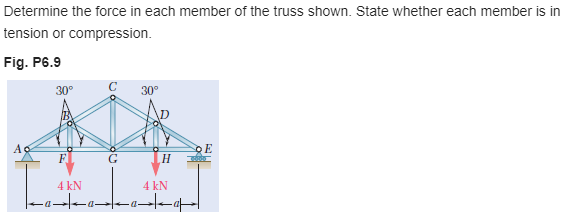

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# member data

a = sym('a', 'positive');
E = sym('E');
A = sym('A');
theta = 30*u.deg;
jointB = a*[1 tan(theta)];
jointC = 2*a*[1 tan(theta)];
jointD = a*[3 tan(theta)];

# truss

t = Truss;
t = t.add('reaction', {'Rax' 'Ray'}, [0 0]);
t = t.add('reaction', {0 'Rey'}, [4*a 0]);
t = t.add('concentrated', [0 -4]*u.kN, [a 0]);
t = t.add('concentrated', [0 -4]*u.kN, [3*a 0]);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', [4*a 0]);
t = t.add('joint', 'F', [a 0]);
t = t.add('joint', 'G', [2*a 0]);
t = t.add('joint', 'H', [3*a 0]);
t = t.add('member', 'Fab', [0 0], jointB);
t = t.add('member', 'Fbc', jointB, jointC);
t = t.add('member', 'Fcd', jointC, jointD);
t = t.add('member', 'Fde', jointD, [4*a 0]);
t = t.add('member', 'Feh', [4*a 0], [3*a 0]);
t = t.add('member', 'Fgh', [2*a 0], [3*a 0]);
t = t.add('member', 'Ffg', [a 0], [2*a 0]);
t = t.add('member', 'Faf', [0 0], [a 0]);
t = t.add('member', 'Fbf', jointB, [a 0]);
t = t.add('member', 'Fbg', jointB, [2*a 0]);
t = t.add('member', 'Fcg', jointC, [2*a 0]);
t = t.add('member', 'Fdg', jointD, [2*a 0]);
t = t.add('member', 'Fdh', jointD, [3*a 0]);

# solution

[us ua fs fa rs ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua, 4) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & 0\\ v_{1} & 0\\ u_{2} & \frac{20.52\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{2} & -\frac{54.02\,a}{A\,\text{E}}\,\mathrm{kN}\\ u_{3} & \frac{13.86\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{3} & -\frac{51.71\,a}{A\,\text{E}}\,\mathrm{kN}\\ u_{4} & \frac{7.19\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{4} & -\frac{54.02\,a}{A\,\text{E}}\,\mathrm{kN}\\ u_{5} & \frac{27.71\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{5} & 0\\ u_{6} & \frac{6.928\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{6} & -\frac{56.33\,a}{A\,\text{E}}\,\mathrm{kN}\\ u_{7} & \frac{13.86\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{7} & -\frac{56.33\,a}{A\,\text{E}}\,\mathrm{kN}\\ u_{8} & \frac{20.78\,a}{A\,\text{E}}\,\mathrm{kN}\\ v_{8} & -\frac{56.33\,a}{A\,\text{E}}\,\mathrm{kN} \end{array}\right)$$

fa_vpa = vpa(fa, 3) %#ok

$$fa\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & -8.0\,\mathrm{kN}\\ \mathrm{Faf} & 6.93\,\mathrm{kN}\\ \mathrm{Fbc} & -4.0\,\mathrm{kN}\\ \mathrm{Fbf} & 4.0\,\mathrm{kN}\\ \mathrm{Fbg} & -4.0\,\mathrm{kN}\\ \mathrm{Fcd} & -4.0\,\mathrm{kN}\\ \mathrm{Fcg} & 4.0\,\mathrm{kN}\\ \mathrm{Fde} & -8.0\,\mathrm{kN}\\ \mathrm{Fdg} & -4.0\,\mathrm{kN}\\ \mathrm{Fdh} & 4.0\,\mathrm{kN}\\ \mathrm{Feh} & 6.93\,\mathrm{kN}\\ \mathrm{Ffg} & 6.93\,\mathrm{kN}\\ \mathrm{Fgh} & 6.93\,\mathrm{kN} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rax} & 0\\ \mathrm{Ray} & 4\,\mathrm{kN}\\ \mathrm{Rey} & 4\,\mathrm{kN} \end{array}\right)$$

# clean up

setassum(old_assum, 'clear');
clear ua_vpa fa_vpa old_assum;